clear all
close all
clc

## load data


%% logfile from REGBOT:
%  1    time 0.000 sec, from Naja (39)
%  2  3  4  5   (mission 0), state 2, entered (thread 1, line 0), events 0x0 (bit-flags)
%  6  7 Motor velocity ref left, right: 0.0000 0.0000
%  8  9 Motor voltage [V] left, right: 0.00 0.00
% 10 13 Wheel velocity [m/s] left, right: 0.0000 0.0000 delay 0.0000 0.0000 (sec)
% 14 15 16 17 Pose x,y,h,tilt [m,m,rad,rad]: 0 0 0 -0.655069
% 18    Battery voltage [V]
data1 = readtable('data/data_upside_down_1.txt',CommentStyle="%");
data1 = fillmissing(data1,'nearest');

data2 = readtable('data/data_wheel_down_1.txt',CommentStyle="%");
data2 = fillmissing(data2,'nearest');

t1 = table2array(data1(:,1));     % time stamps
u_L1 = table2array(data1(:,8));   % left motor voltage
u_R1 = table2array(data1(:,9));   % right motor voltage
v_L1 = table2array(data1(:,10));  % left motor velocity 
v_R1 = table2array(data1(:,11));  % right motor velocity
T_s1 = t1(2) - t1(1);              % compute sampling time

idx_out = find(u_L1 > 3,1,'first');
idx_end = find(t1 > 6,1,'first');

t2 = table2array(data2(:,1));     % time stamps
u_L2 = table2array(data2(:,8));   % left motor voltage
u_R2 = table2array(data2(:,9));   % right motor voltage
v_L2 = table2array(data2(:,10));  % left motor velocity 
v_R2 = table2array(data2(:,11));  % right motor velocity
T_s2 = t2(2) - t2(1);              % compute sampling time

## Creat plot of input output for wheel up

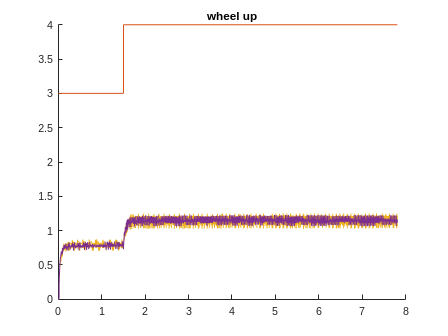

% Create a figure with subplots
figure;
title('wheel up'); 
hold on
plot(t1,u_L1)
hold on
plot(t1,u_R1)
hold on
plot(t1,v_L1)
hold on
plot(t1,v_R1)

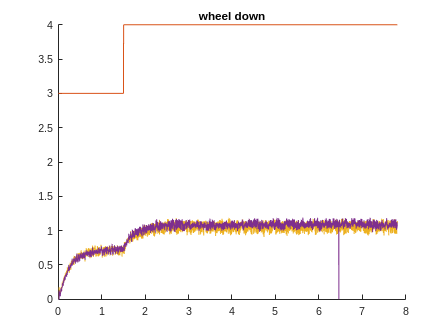

% Create a figure with subplots
figure;
title('wheel down'); 
hold on
plot(t2,u_L2)
hold on
plot(t2,u_R2)
hold on
plot(t2,v_L2)
hold on
plot(t2,v_R2)

## claculate Transferfuntions for GL1 (left wheelup) GR1 (rhigte wheelup) GL2 (left wheel down)  GR2 (rhigte wheel down)


iddl1 = iddata(v_L1(idx_out:idx_end),u_L1(idx_out:idx_end),T_s1);
iddr1 = iddata(v_R1(idx_out:idx_end),u_R1(idx_out:idx_end),T_s1);

iddl2 = iddata(v_L2(idx_out:idx_end),u_L2(idx_out:idx_end),T_s1);
iddr2 = iddata(v_R2(idx_out:idx_end),u_R2(idx_out:idx_end),T_s1);

np = 1;
nz = 0;



GL1 = tfest(iddl1,np,nz); 

GR1 = tfest(iddr1,np,nz); 

GL2 = tfest(iddl2,np,nz); 

GL2 = tfest(iddr2,np,nz);

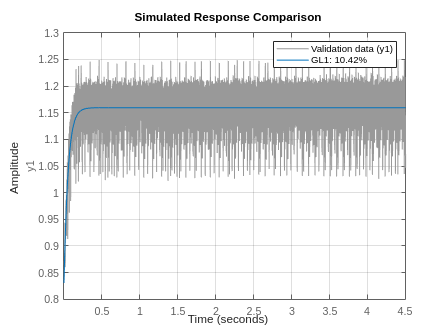


%step(GL)

%figure(2);
compare(GL1,iddl1); % Compare and plot real and simulated outputs
grid on;